# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgml.mlx
    ----------------
    This code solves the stochastic growth model with endogenous labor supply using value function iteration.

%}

## Model: Stochastic Growth Model with Government Sector.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} +\frac{g_t^{1-\sigma}}{1-\sigma} \right] \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha}\end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t+ i_t \end{array} \ ,$$



$$\begin{array}{r l}c_t + i_t = (1-\tau_t^k)r_tk_t+(1-\tau_t^n)w_tn_t+\delta\tau_t^kk_t+g_t \end{array} \ ,$$



$$\begin{array}{r l}g_t = \tau_t^k r_tk_t+\tau_t^nw_tn_t-\delta\tau_t^kk_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} n_t =1\end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$. 

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.
disp(fieldnames(par));

    {'beta'     }
    {'sigma'    }
    {'r'        }
    {'w'        }
    {'n'        }
    {'tauk'     }
    {'taun'     }
    {'alpha'    }
    {'delta'    }
    {'sigma_eps'}
    {'rho'      }
    {'mu'       }
    {'seed'     }
    {'T'        }
    {'kss'      }
    {'klen'     }
    {'kmax'     }
    {'kmin'     }
    {'kgrid'    }
    {'Alen'     }
    {'m'        }
    {'Agrid'    }
    {'pmat'     }



## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal condition is


$$(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $k_t$ and $A_t$, and we use the same grid for $k_{t+1}$ as $k_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) = (A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $k_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $k_t, k_{t+1},$ and $A_t$.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Starting Value Function Iteration------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 399 iterations.

------------End of Value Function Iteration------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 81.8281 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the stochastic growth model. The difference now is that labor supply is negatively correlated with productivity. This is because when $A_t$ is low, labor supply increases to boost output; when $A_t$ is high, less labor is needed to produce a given level of output and more time can be spent on leisure. Given a Cobb-Douglas production function with constant returns to scale, the marginal product of labor is increasing with capital so $n_t$ increases with $k_t$.

The time series data have similar qualitative results as in the model without labor supply. Labor itself is relatively constant (see the units of the graph). 

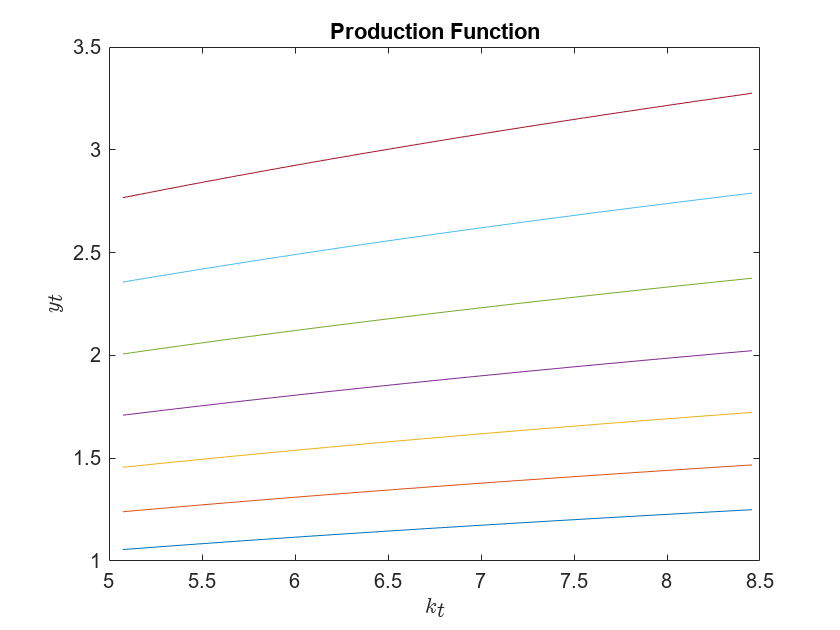

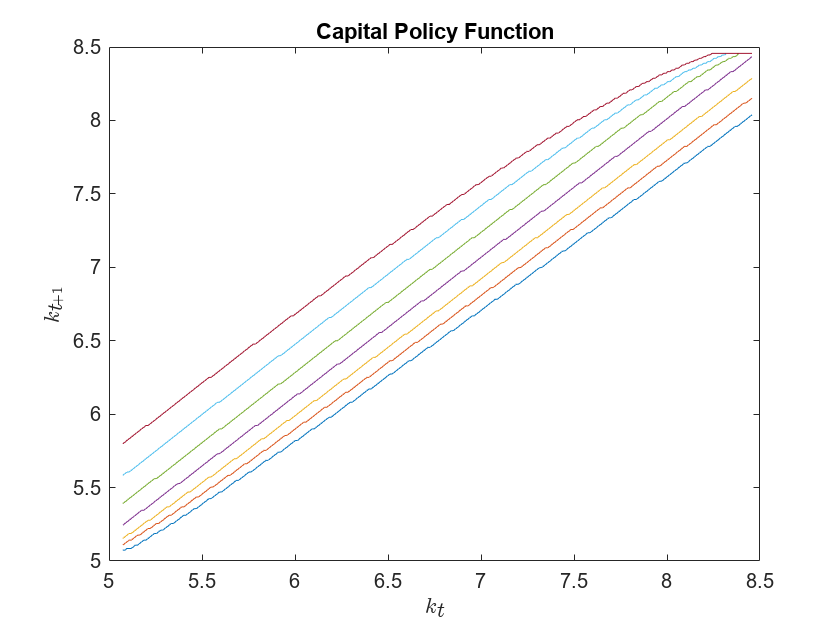

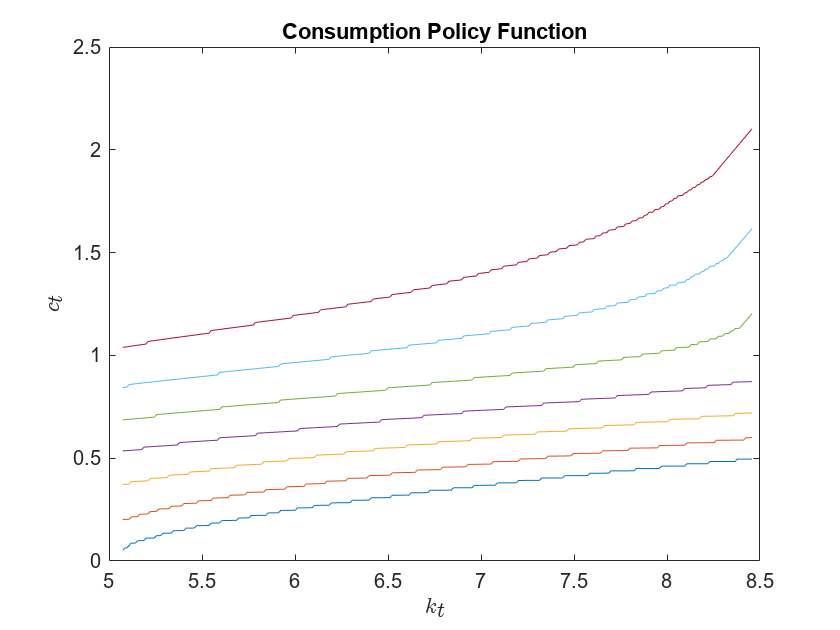

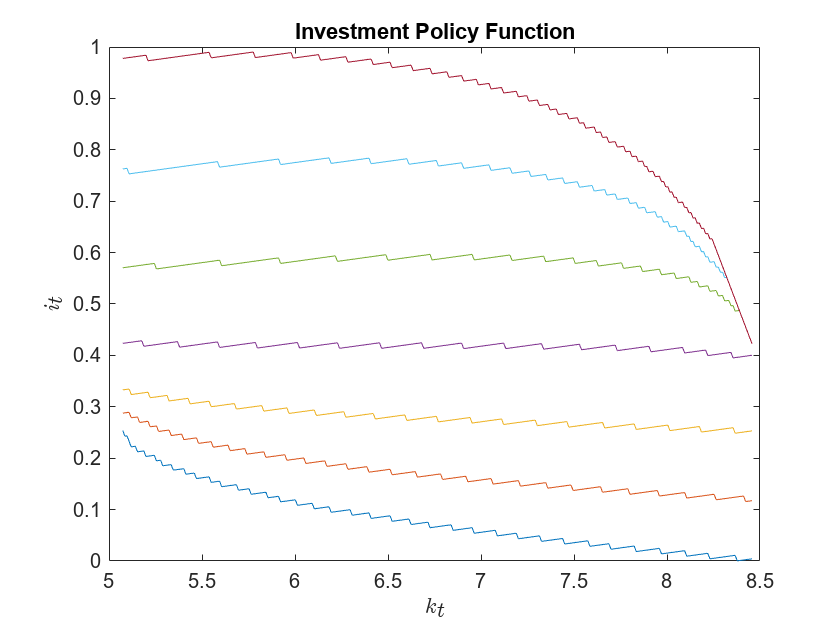

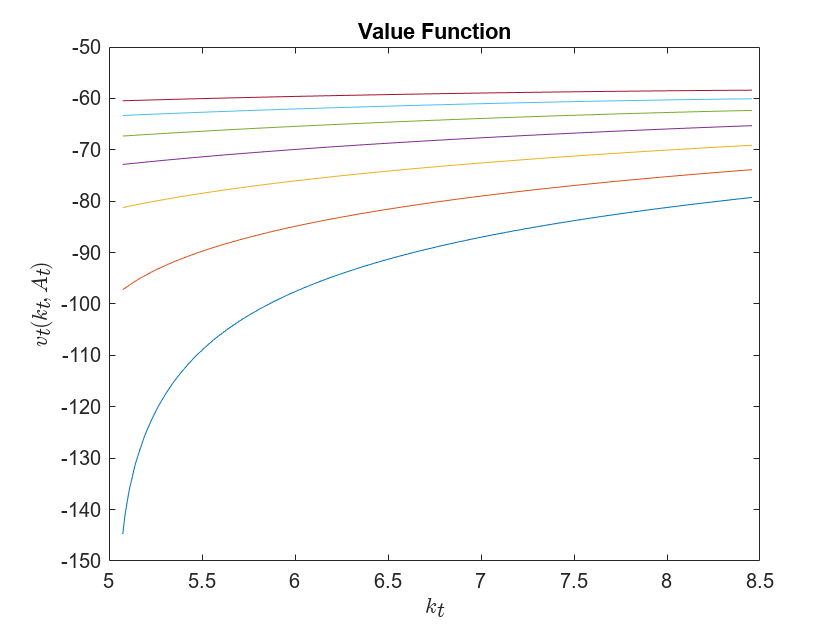

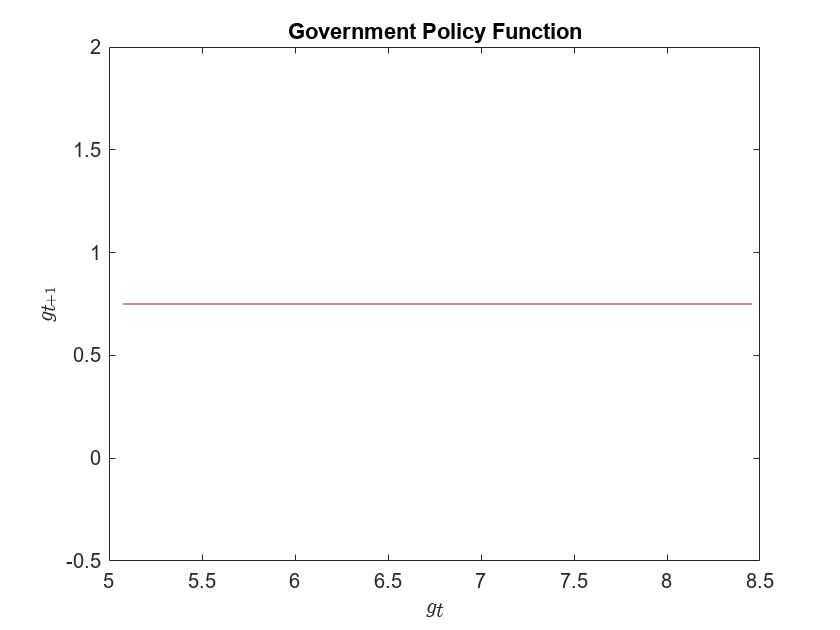

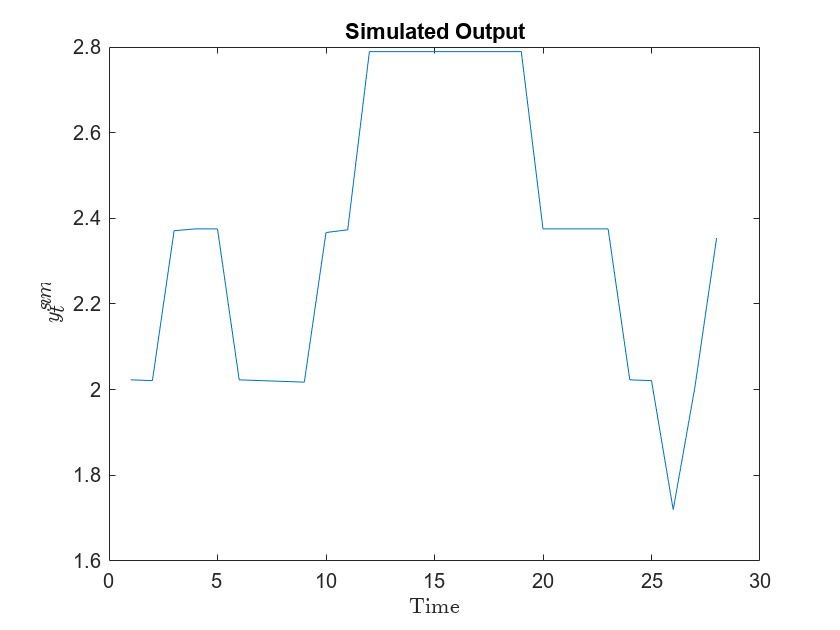

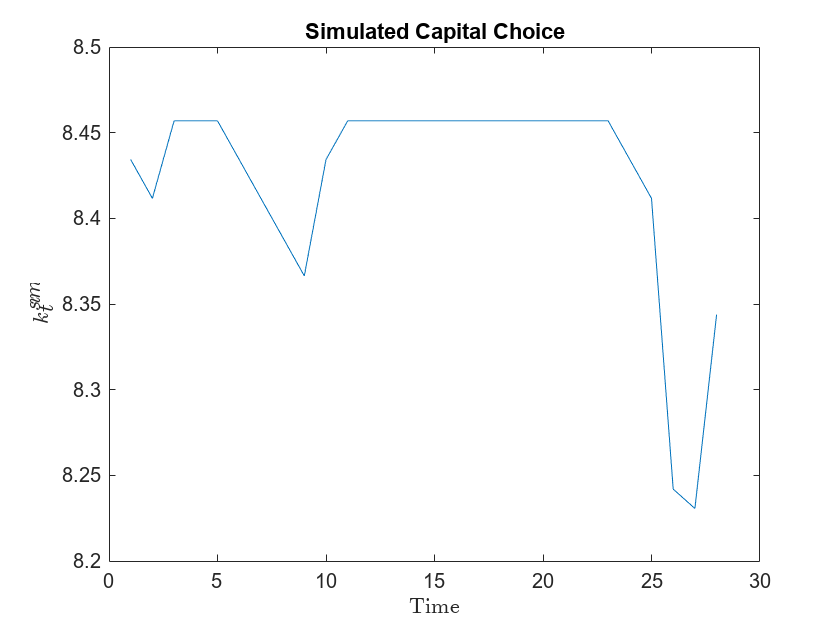

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.

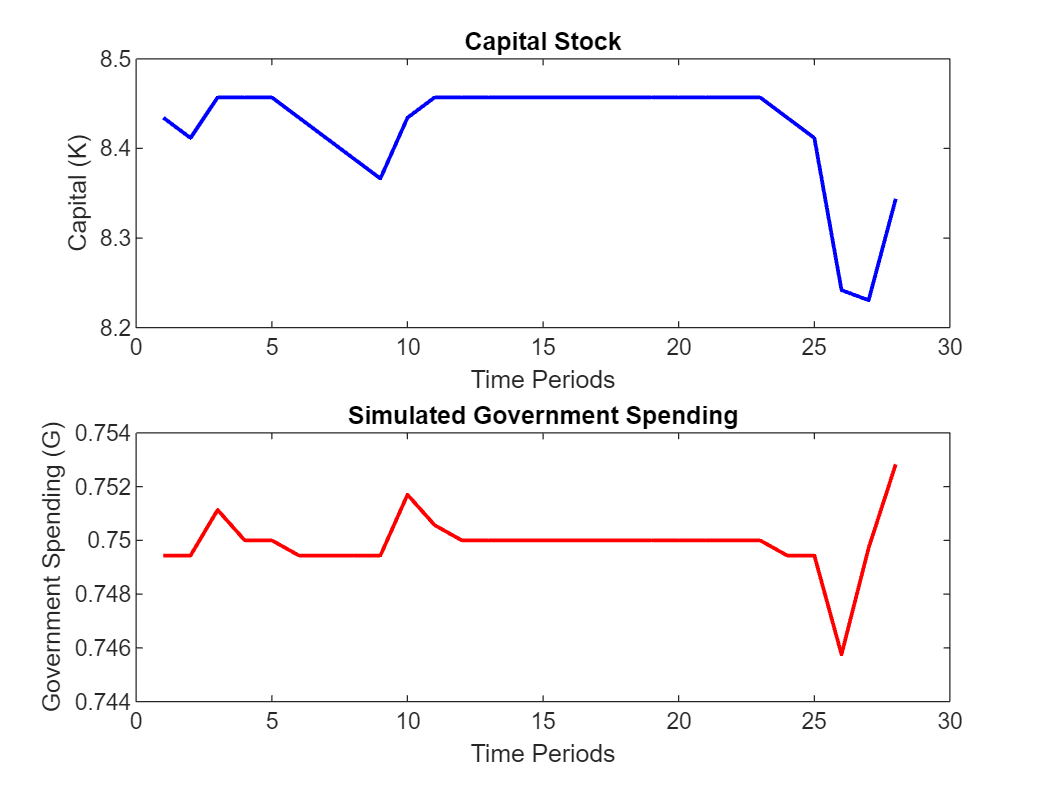

figure;

% First subplot: Capital Stock
subplot(2,1,1);  
plot(sim.ksim, 'b-', 'LineWidth', 1.5);
title('Capital Stock');
xlabel('Time Periods');
ylabel('Capital (K)');
grid off;

% Second subplot: Government Spending
subplot(2,1,2);  
plot(sim.gsim, 'r-', 'LineWidth', 1.5);
title('Simulated Government Spending');
xlabel('Time Periods');
ylabel('Government Spending (G)');
grid off;

## Analysis.

To check the validity of the model, we compute statistics of interest and see how the data line up. In some cases, these are explicitly targeted by adjusting or estimating parameters that govern the behavior of the simulated data. In our case, we just set these exogenously from the literature, which in turn obtain these from data or estimation. The model differs from the literature so this model is off from the data, see Table 5.1 in Adda and Cooper.

% Compute the variables corresponding to data. The model assumes the data are detrended.
ysim = sim.ysim; % Output.
ksim = sim.ksim; % Capital Stock.
isim = sim.isim; % Investment.
csim = sim.csim; % Consumption.
gsim = sim.gsim; % Government.

% Std. Dev of variables relative to output.
cvar = sqrt(var(csim))/sqrt(var(ysim));
ivar = sqrt(var(isim))/sqrt(var(ysim));
gvar = sqrt(var(gsim))/sqrt(var(ysim));
kvar = sqrt(var(ksim))/sqrt(var(ysim));


fprintf('The Std. Dev of Capital Relative to Output is: %0.4f',kvar)

The Std. Dev of Capital Relative to Output is: 0.1845

fprintf('The Std. Dev of Consumption Relative to Output is: %0.4f',cvar)

The Std. Dev of Consumption Relative to Output is: 0.9460

fprintf('The Std. Dev of Investment Relative to Output is: %0.4f',ivar)

The Std. Dev of Investment Relative to Output is: 0.1312

fprintf('The Std. Dev of Government Relative to Output is: %0.4f',gvar)

The Std. Dev of Government Relative to Output is: 0.0033

## Apply real-time data for Vietnam

### Load the dataset

%% Import dataset
path = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv");
data = readtable(path)

data = 28×12 table
    Year    GDP_constant2015US__    GDPPerCapita_constant2015US__    GDPGrowthRate___    FDIInflow_BoP_US__    GrossFixedCapitalFormation_constant2015US__    GrossCapitalFormationGrowth___    GrossFixedCapitalFormation__OfGDP_    FinalConsumptionExpenditure_constant2015US__    Population_Total    ConsumptionPerCapita_constant2015US__    InvestmentPerCapita_constant2015US__
    ____    ____________________    _____________________________    ________________    __________________    ___________________________________________    ______________________________    __________________________________    ___________________________

### Exploratory data analysis (EDA)

disp(data.Properties.VariableNames)

  Columns 1 through 5

    {'Year'}    {'GDP_constant201…'}    {'GDPPerCapita_co…'}    {'GDPGrowthRate___'}    {'FDIInflow_BoP_U…'}

  Columns 6 through 10

    {'GrossFixedCapit…'}    {'GrossCapitalFor…'}    {'GrossFixedCapit…'}    {'FinalConsumptio…'}    {'Population_Total'}

  Columns 11 through 12

    {'ConsumptionPerC…'}    {'InvestmentPerCa…'}



%% Extract actual data & convert to log values
actual_t=  1:length(data.Year);       % Time
actual_i = log(data.InvestmentPerCapita_constant2015US__);      % Empirical investment
actual_c = log(data.ConsumptionPerCapita_constant2015US__);     % Empirical consumption
actual_y = log(data.GDPPerCapita_constant2015US__);                    % GDP per capita
%actual_g = data(:,5);                                             % Empirical government spending
%actual_k = data.;                                                 % Empirical capital

### Visualize the empirical data vs simulated data

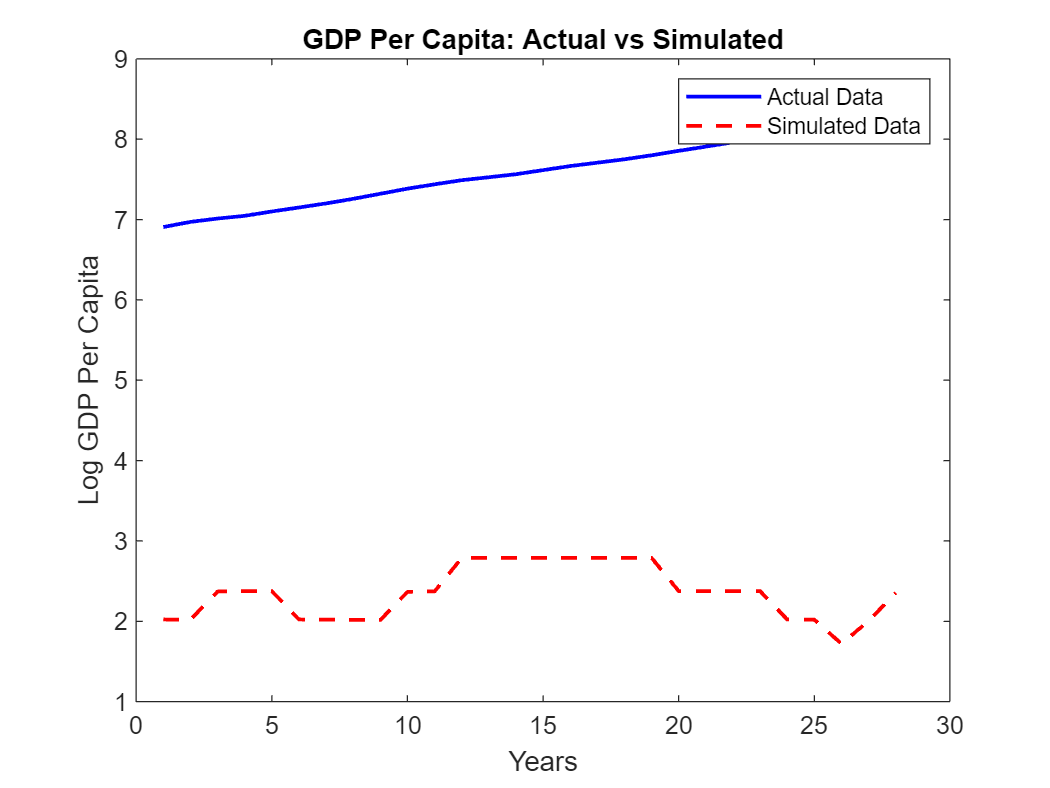

%% Plot actual vs. simulated GDP per capita
figure;
plot(actual_t, actual_y, 'b-', 'LineWidth', 1.5); % Actual data
hold on;
plot(sim.ysim, 'r--', 'LineWidth', 1.5); % Simulated data
title('GDP Per Capita: Actual vs Simulated');
xlabel('Years'); ylabel('Log GDP Per Capita');
legend('Actual Data', 'Simulated Data');

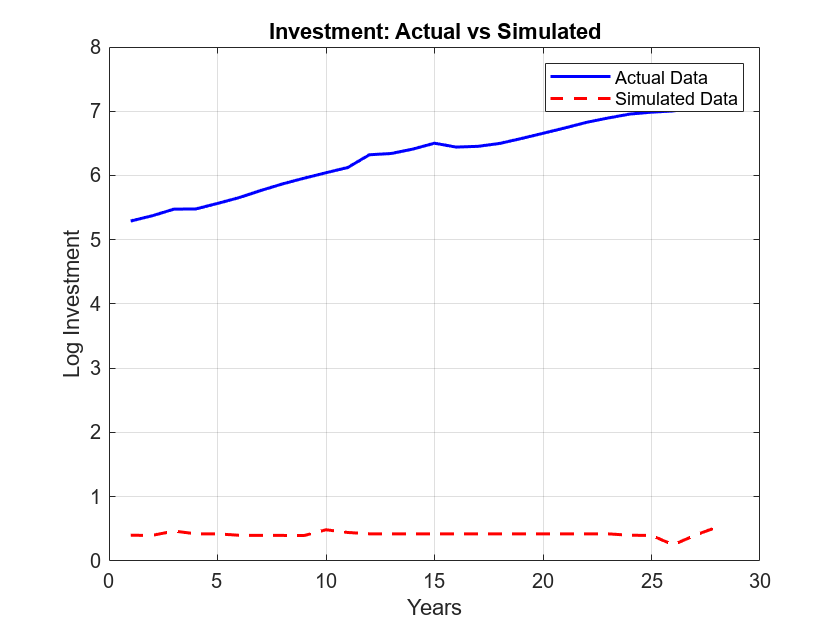

%% Plot Investment
figure;
plot(actual_t, actual_i, 'b-', 'LineWidth', 1.5); hold on;
plot(sim.isim, 'r--', 'LineWidth', 1.5);
title('Investment: Actual vs Simulated');
xlabel('Years'); ylabel('Log Investment');
legend('Actual Data', 'Simulated Data');
grid on;

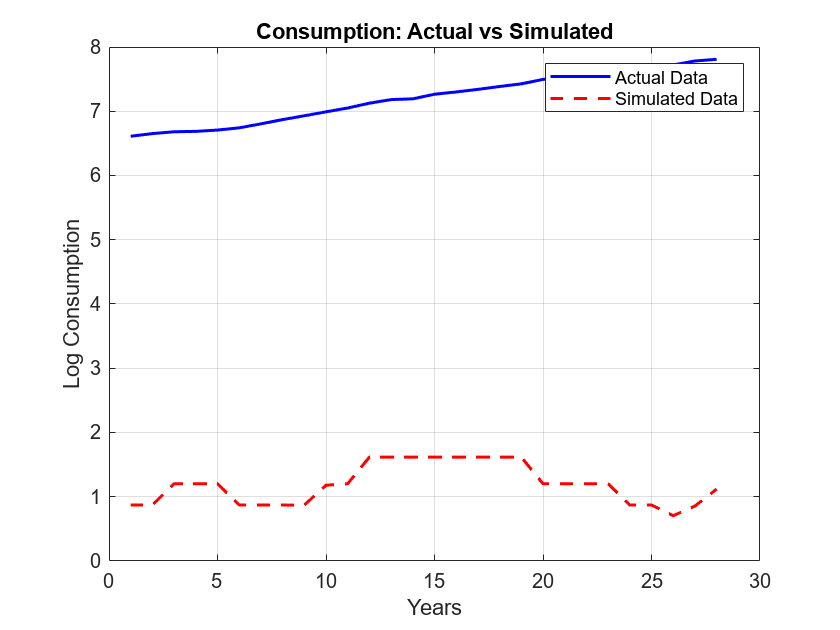

%% Plot Consumption
figure;
plot(actual_t, actual_c, 'b-', 'LineWidth', 1.5); hold on;
plot(sim.csim, 'r--', 'LineWidth', 1.5);
title('Consumption: Actual vs Simulated');
xlabel('Years'); ylabel('Log Consumption');
legend('Actual Data', 'Simulated Data');
grid on;

%% Expansionary Fiscal & Monetary Policy Scenario  
par_expansion = par;  % Create a copy of the parameters
par_expansion.tauk = par.tauk * 0.8;  % Reduce tax rate by 20%
par_expansion.taun = par.taun * 0.85; % Reduce income tax rate by 15%

%% Solve & Simulate Expansionary Policy  
sol_expansion = solve.grow(par_expansion);

------------Starting Value Function Iteration------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 376 iterations.

------------End of Value Function Iteration------------


sim_expansion = simulate.grow(par_expansion, sol_expansion);

%% Tightening Fiscal & Monetary Policy Scenario  
par_tightening = par;  % Copy original parameters
par_tightening.tauk = par.tauk * 1.2;  % Increase tax rate on capital by 20%
par_tightening.taun = par.taun * 1.15; % Increase income tax rate by 15%

%% Solve & Simulate Tightening Policy  
sol_tightening = solve.grow(par_tightening);

------------Starting Value Function Iteration------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.
Iteration: 425.
Iteration: 450.
Iteration: 475.
Iteration: 500.
Iteration: 525.
Iteration: 550.
Iteration: 575.
Iteration: 600.
Iteration: 625.
Iteration: 650.

Converged in 667 iterations.

------------End of Value Function Iteration------------


sim_tightening = simulate.grow(par_tightening, sol_tightening);

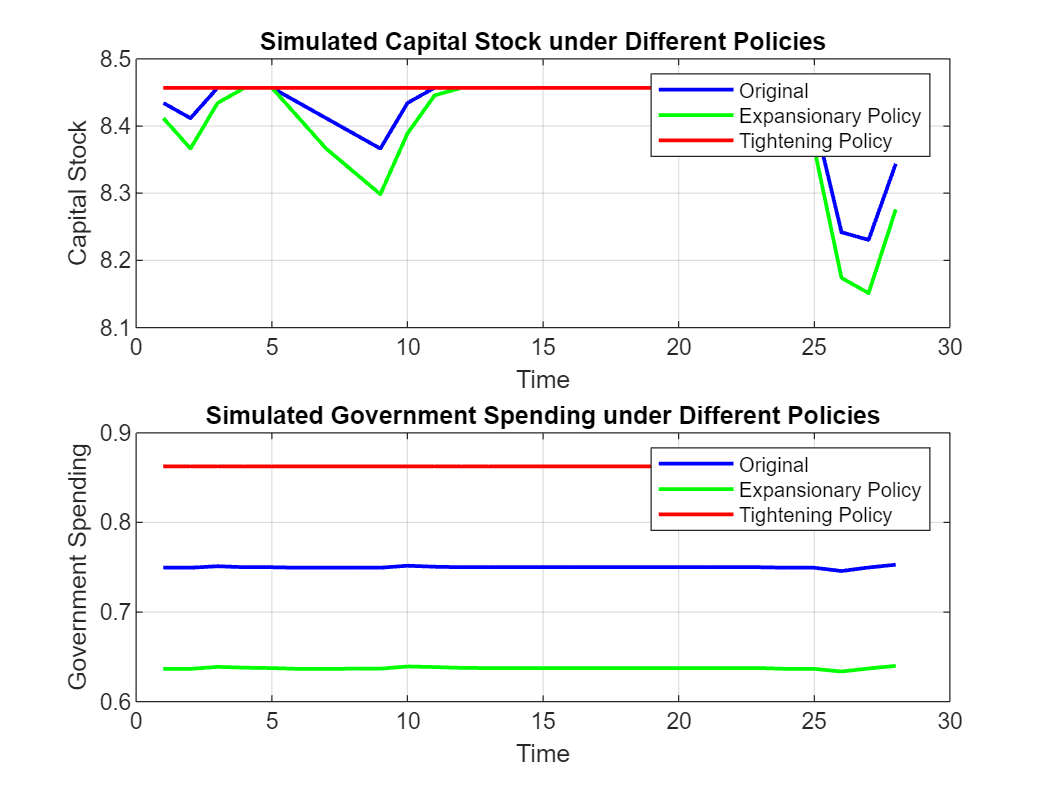

%% Compare Results  
figure;
subplot(2,1,1);
plot(sim.ksim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.ksim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.ksim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Capital Stock under Different Policies');
xlabel('Time'); ylabel('Capital Stock');
grid on;

subplot(2,1,2);
plot(sim.gsim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.gsim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.gsim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Government Spending under Different Policies');
xlabel('Time'); ylabel('Government Spending');
grid on;

## Statistical Analysis of Simulated Government Spending

%% Compute statistics for original scenario
gsim_original = sim.gsim;
min_gsim_original = min(gsim_original);
max_gsim_original = max(gsim_original);
mean_gsim_original = mean(gsim_original);
median_gsim_original = median(gsim_original);
std_gsim_original = std(gsim_original);

%% Compute statistics for expansionary policy scenario
gsim_expansion = sim_expansion.gsim;
min_gsim_expansion = min(gsim_expansion);
max_gsim_expansion = max(gsim_expansion);
mean_gsim_expansion = mean(gsim_expansion);
median_gsim_expansion = median(gsim_expansion);
std_gsim_expansion = std(gsim_expansion);

%% Compute statistics for tightening policy scenario
gsim_tightening = sim_tightening.gsim;
min_gsim_tightening = min(gsim_tightening);
max_gsim_tightening = max(gsim_tightening);
mean_gsim_tightening = mean(gsim_tightening);
median_gsim_tightening = median(gsim_tightening);
std_gsim_tightening = std(gsim_tightening);

% Create a table with results
T = table({'Original'; 'Expansionary'; 'Tightening'}, ...
    [min_gsim_original; min_gsim_expansion; min_gsim_tightening], ...
    [max_gsim_original; max_gsim_expansion; max_gsim_tightening], ...
    [mean_gsim_original; mean_gsim_expansion; mean_gsim_tightening], ...
    [median_gsim_original; median_gsim_expansion; median_gsim_tightening], ...
    [std_gsim_original; std_gsim_expansion; std_gsim_tightening], ...
    'VariableNames', {'Scenario', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

% Display table
disp(T);

        Scenario          Min        Max       Mean      Median      StdDev  
    ________________    _______    _______    _______    ______    __________

    {'Original'    }    0.74576    0.75283     0.7499      0.75     0.0011028
    {'Expansionary'}    0.63365    0.63999    0.63737    0.6375     0.0011092
    {'Tightening'  }     0.8608    0.86352     0.8625    0.8625    0.00040265

